### **Métoda da Bisseção**


$$x^{k+1} = \frac{a^{k}+b^{k}}{2}$$
 

Vamos encontrar o zero da função $f(x) = e^{x}+x$ no intervalo de $[-2,2]$ utilizando o método da bisseção com precisão igual ou menor que $10^{-4}$.

Graficamente, 

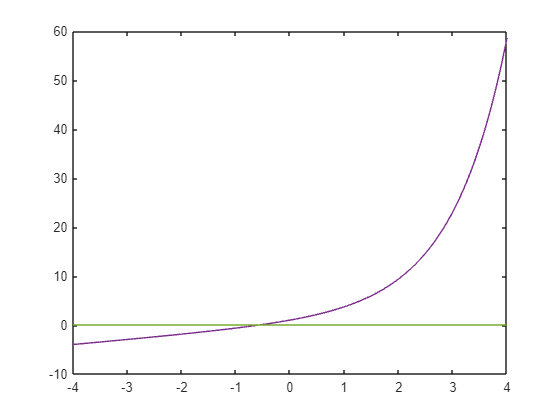

x= -4:0.01:4;
y = exp(x)+x;
plot(x,y)
y1 = 0*x;
hold on 
plot(x,y1)

Bisseção com 

**Implementação do método da Bisseção**

format long
%Entradas
a = -2;
b = 2;
tol = 10^(-4);
%Avaliando a função em x=a e x=b
fa = exp(a) + a;
fb = exp(b) + b;
%Inicializando o chute
x0 = (a+b)/2;
fx0 = exp(x0) + x0;

%Critério de parada
er = abs(b-a)/2; 
%Looping
k = 0;
while (er > tol)
    k = k + 1;
    if fa*fx0 < 0
        b = x0;
        fb = exp(b) + b;
    else
        a = x0;
        fa = exp(a) + a;
    end
    x0 = (a+b)/2; %Atualização do chute
    fx0 = exp(x0) + x0;
    er = abs(b-a)/2;
end
fprintf('Uma aproximação para o erro da função é x = %f',x0);

Uma aproximação para o erro da função é x = -0.567200

fprintf('A quantidade de iterações foi k = %d',k);

A quantidade de iterações foi k = 15

Comparando com a conta para o número de iterações temos:


$$iteracoes = \frac{log(b-a) - log(tol)}{log(2)}$$


iteracoes = (log10(4)-log10(10^(-4)))/log10(2) 

iteracoes =   15.287712379549451


**Como implementar e obter o resultado de todas as iterações?**

*---> Foi implementado um exercicio passado pelo professor Angelo na aula do dia 14/03 ( arquivo: exercicio Angelo_aula_14_03.mlx )*